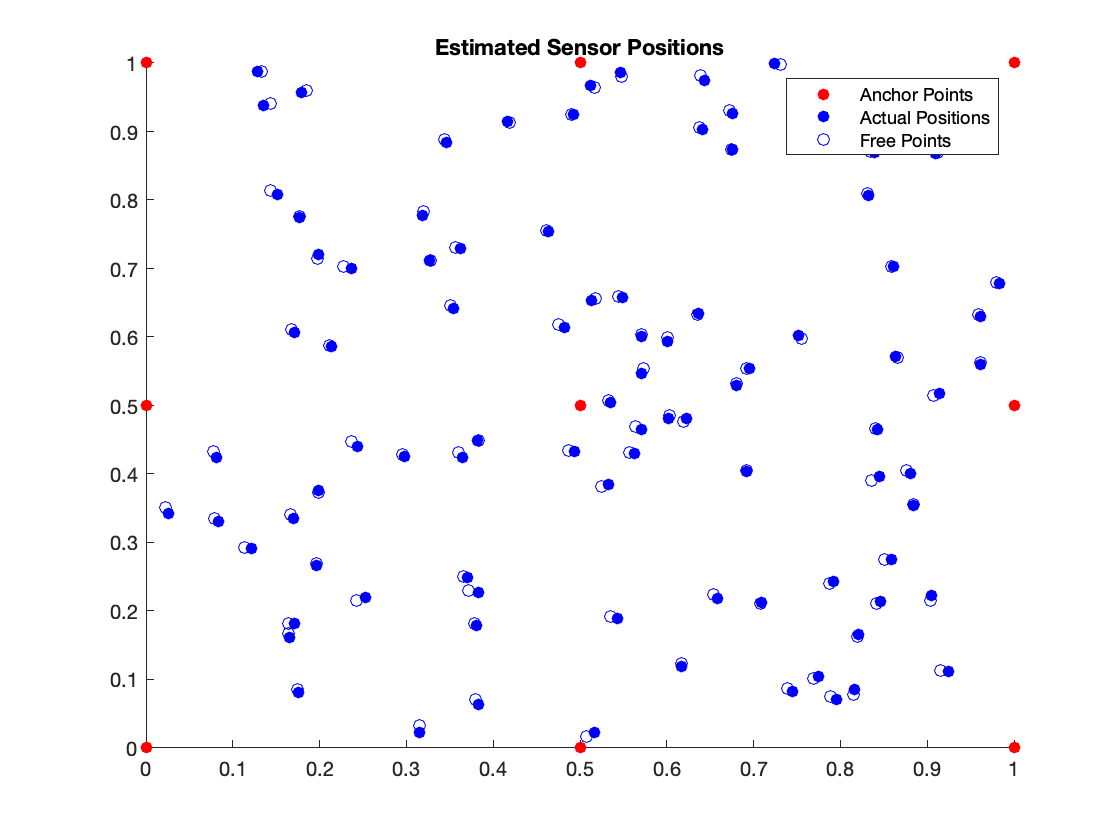

N = 100; R = 0.4; s = 0.05;
[E, pos, K] = network_loc_data(N, R);
pos_anchor = pos(N-K+1:N, :);
L = size(E,1);
d = sqrt(sum( (pos(E(:,1),:) - pos(E(:,2),:)).^2, 2));
rho = (1 + s*randn(L,1)) .* d;
[pos_free, cost, lambdas] = network_loc(N, E, pos_anchor, rho); % your function
scatter(pos_anchor(:,1), pos_anchor(:,2), 'red', 'filled');
hold on;
scatter(pos(1:N-K,1),pos(1:N-K,2),'blue', 'filled');
scatter(pos_free(:,1), pos_free(:,2), 'blue');
xlim([0 1]); ylim([0 1]);
title('Estimated Sensor Positions');
legend(["Anchor Points", "Actual Positions", "Free Points"]);
hold off;

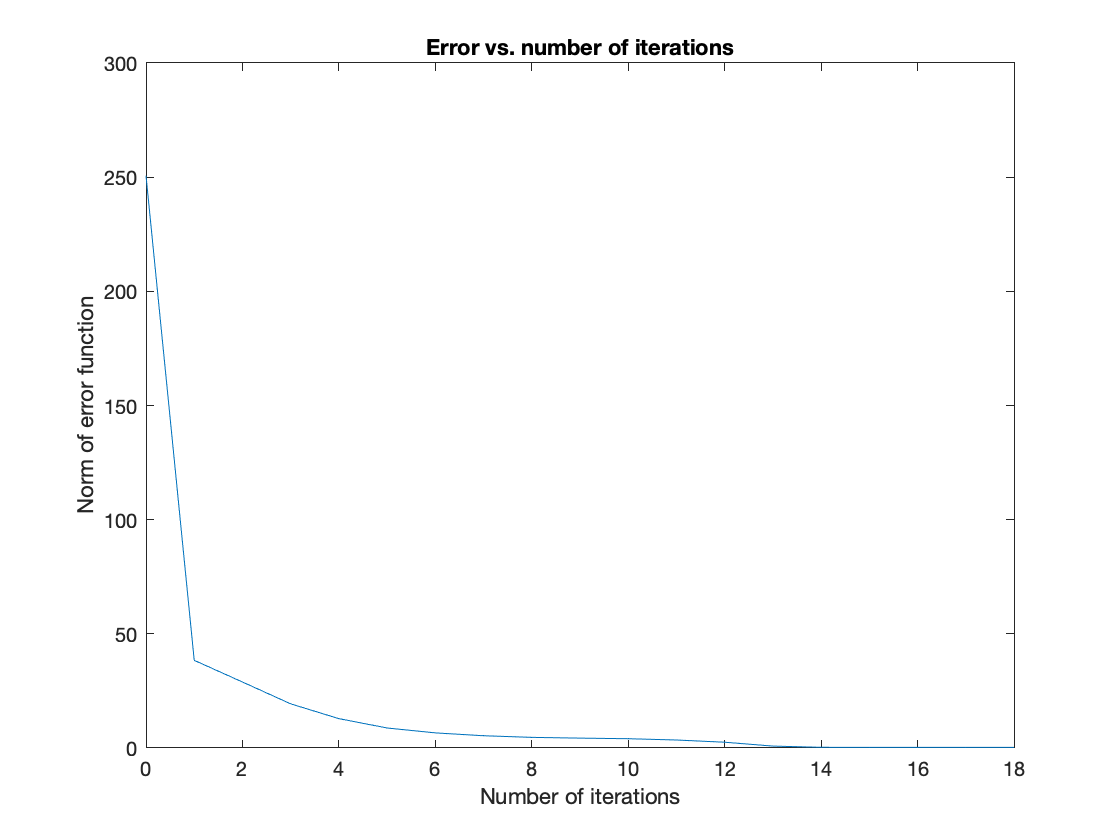

plot(0:length(cost)-1, cost); xlabel('Number of iterations'); ylabel('Norm of error function'); title('Error vs. number of iterations');

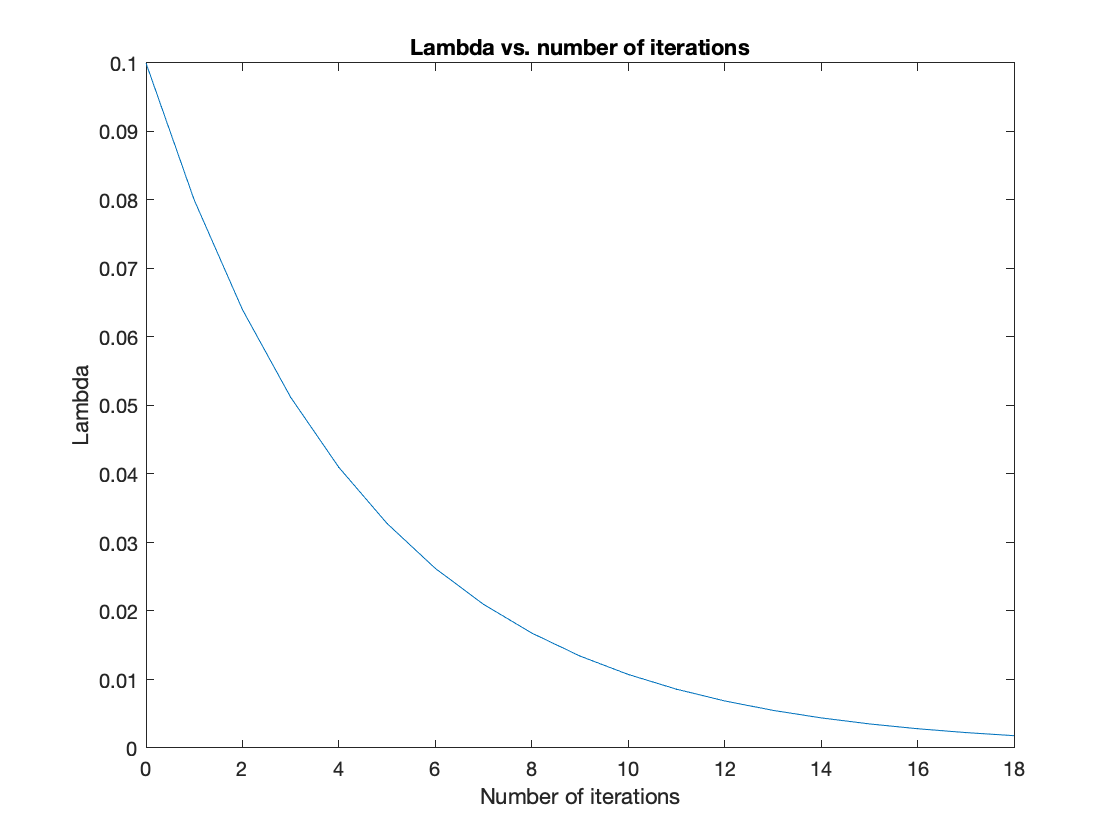

plot(0:length(lambdas)-1, lambdas); xlabel('Number of iterations'); ylabel('Lambda'); title('Lambda vs. number of iterations');

cost(end)

ans = 0.2837